# Problem 1

interr = 'latex';
% interr = 'none';
set(groot,'defaulttextinterpreter',interr);  
set(groot, 'defaultAxesTickLabelInterpreter',interr);  
set(groot, 'defaultLegendInterpreter',interr);

## Preliminary Calculations and Constants

Re = 6378.1; % Earth radius, km
mu = 398600.4415; % Earth mu, km^3/s^2

Current Orbit Characteristics:

e1 = 0; a1 = 1.025*Re; 
v1_mag_0 = sqrt(mu/a1)

v1_mag_0 = 7.8084

Final Orbit Characteristics:

e2 = 0; a2 = 6.611*Re; 
v2_mag_0 = sqrt(mu/a2)

v2_mag_0 = 3.0746

#### i) Transfer Orbit Characteristics: Hohmann

[aT_1, eT_1, TOF_total_1, ...
    v1_0_1, gamma_1_N_1, v1_N_1, dv1_1, alpha1_1, beta1_1, ...
    v2_0_1, gamma_2_N_1, v2_N_1, dv2_1, alpha2_1, beta2_1, ...
    dv_mag_total_1] = coplanartransfer(a1,a2,0,pi,mu)

aT_1 = 2.4352e+04

eT_1 = 0.7315

TOF_total_1 = 1.8909e+04

v1_0_1 =          0
    7.8084


gamma_1_N_1 = 0

v1_N_1 =          0
   10.2749


dv1_1 =          0
    2.4665


alpha1_1 = 0

beta1_1 = 3.1416

v2_0_1 =          0
    1.5931


gamma_2_N_1 = 2.9802e-08

v2_N_1 =          0
    3.0746


dv2_1 =          0
    1.4815


alpha2_1 = 6.1848e-08

beta2_1 = 3.1416

dv_mag_total_1 = 3.9480

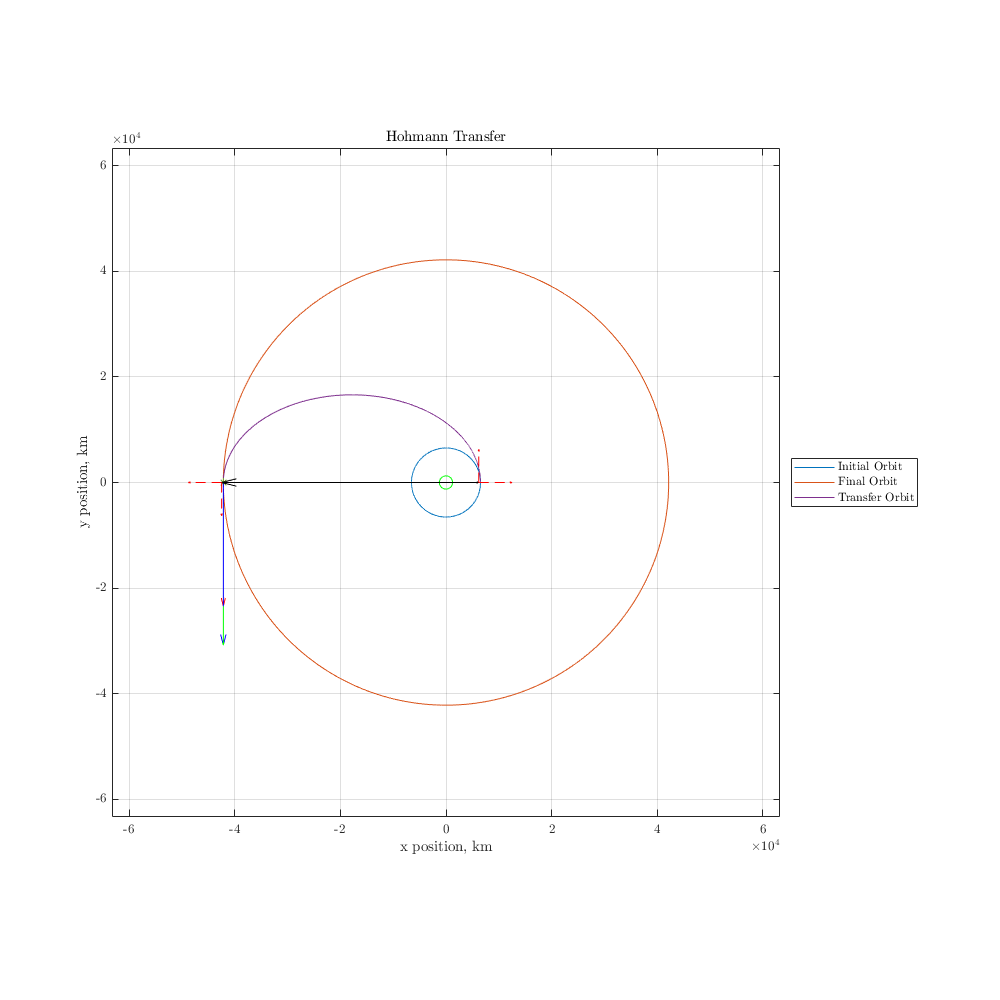

plotinitfin(a1,0,a2,0)
hold on
plottransfer(aT_1,eT_1,0,pi)
title('Hohmann Transfer')
xlabel('x position, km'), ylabel('y position, km')
plotvel(aT_1,eT_1,pi,v1_0_1,'r',0,0) % pre, pos1
plotvel(aT_1,eT_1,pi,v1_N_1,'b',0,0) % post, pos1
plotvel(aT_1,eT_1,pi,dv1_1,'g',[1; v1_0_1],0) % dv, pos1
plotpos(aT_1,eT_2,0,'k',0)
plotpos(aT_1,eT_2,pi,'k',0)
legend('Initial Orbit','Final Orbit', '','Transfer Orbit','','','','','','location','eastoutside')
set(gcf,'position',[0,0,1000,1000])
hold off


phase1 = pi - TOF_total_1 * sqrt(mu/a2^3), phase1_deg = rad2deg(phase1)

phase1 = 1.7628

phase1_deg = 101.0003

#### ii) Transfer Orbit Characteristics: 150 Degree Transfer Angle

[aT_2, eT_2, TOF_total_2, ...
    v1_0_2, gamma_1_N_2, v1_N_2, dv1_2, alpha1_2, beta1_2, ...
    v2_0_2, gamma_2_N_2, v2_N_2, dv2_2, alpha2_2, beta2_2, ...
    dv_mag_total_2] = coplanartransfer(a1,a2,30*pi/180,pi,mu)

aT_2 = 2.4165e+04

eT_2 = 0.7449

TOF_total_2 = 1.8376e+04

v1_0_2 =          0
    7.8084


gamma_1_N_2 = 0.2227

v1_N_2 =     2.2675
   10.0152


dv1_2 =     2.2675
    2.2069


alpha1_2 = 0.7990

beta1_2 = 2.3426

v2_0_2 =          0
    1.5528


gamma_2_N_2 = 0

v2_N_2 =          0
    3.0746


dv2_2 =          0
    1.5218


alpha2_2 = 0

beta2_2 = 3.1416

dv_mag_total_2 = 4.6859

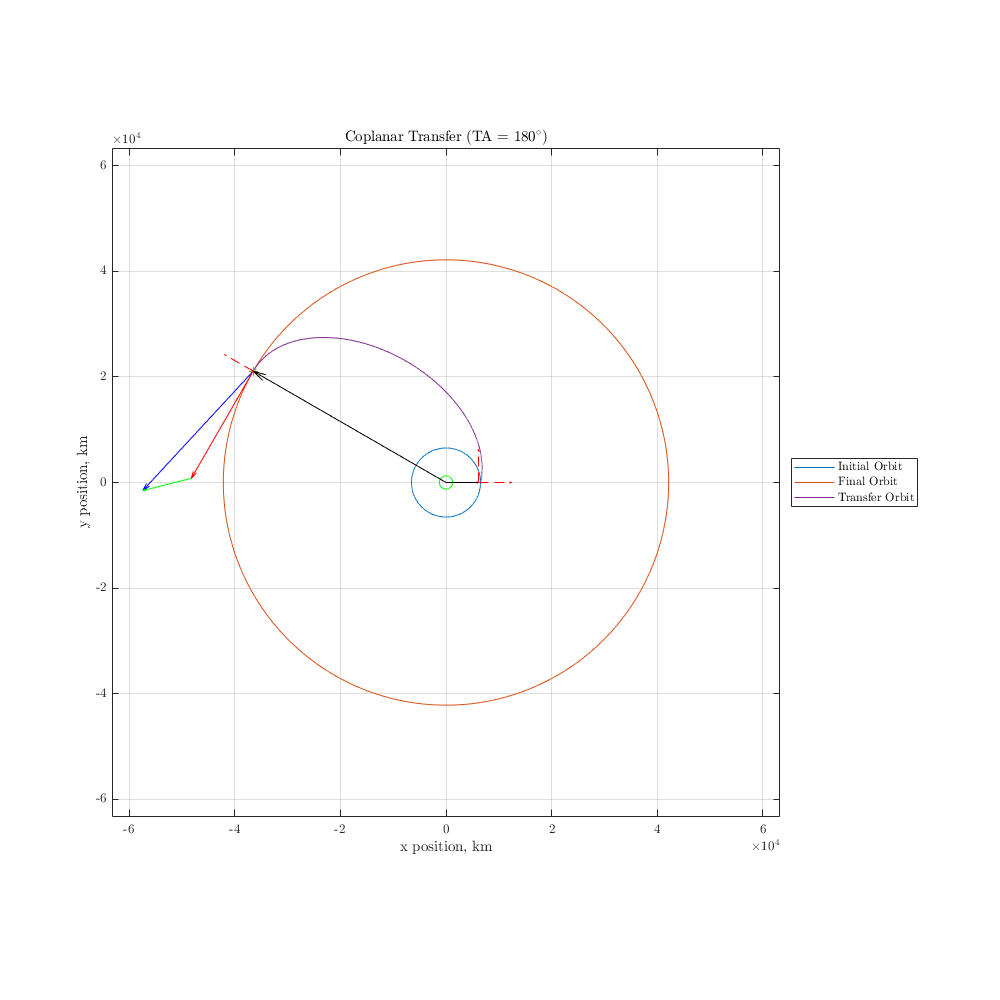

plotinitfin(a1,0,a2,0)
hold on
plottransfer(aT_2,eT_2,30*pi/180,pi)
title('Coplanar Transfer (TA = $180^{\circ}$)')
xlabel('x position, km'), ylabel('y position, km')
plotvel(aT_2,eT_2,pi,v1_0_2,'r',0,30*pi/180) % pre, pos1
plotvel(aT_2,eT_2,pi,v1_N_2,'b',0,30*pi/180) % post, pos1
plotvel(aT_2,eT_2,pi,dv1_2,'g',[1; v1_0_1],30*pi/180) % dv, pos1
plotpos(aT_2,eT_2,0,'k',0)
plotpos(aT_2,eT_2,pi,'k',30*pi/180)
legend('Initial Orbit','Final Orbit', '','Transfer Orbit','','','','','','location','eastoutside')
set(gcf,'position',[0,0,1000,1000])
hold off


phase2 = pi - TOF_total_2 * sqrt(mu/a2^3), phase2_deg = rad2deg(phase2)

phase2 = 1.8017

phase2_deg = 103.2291

### Function 1: Transfer Characteristics (Circle to Circle)

Can change to work with any starting and ending orbits, once that works, bi-elliptic/multiburn transfer can be done through recursion or multiple function calls

Transfer starting at periapsis of transfer orbit to transfer angle on orbit

a1 and a2 in km

ths1 and ths2 are initial and final true anomalies on transfer orbit

function [aT, eT, TOF_total, ...
    v1_0, gamma_1_N, v1_N, dv1, alpha1, beta1, ...
    v2_0, gamma_2_N, v2_N, dv2, alpha2, beta2, ...
    dv_mag_total] = coplanartransfer(a1,a2,ths1,ths2,mu)

Transfer Orbit Characteristics:

eT = (a2 - a1)/(a2 + a1 * cos(ths1));
aT = a2/(1+eT);
E1 = eccenAnom(ths1,eT);
E2 = eccenAnom(ths2,eT);
TOF1 = sqrt(aT^3/mu) * (E1 - eT*sin(E1));
TOF2 = sqrt(aT^3/mu) * (E2 - eT*sin(E2));
TOF_total = TOF2-TOF1;

1st Thrust Point Conditions (Pre-Maneuver: Initial Orbit): (change this to be able to accomodate other starting orbit)

r1_mag = a1; v1_mag_0 = sqrt(mu*(2/r1_mag-1/a1)); 
v1_0 = [0 v1_mag_0]';

1st Thrust Point Conditions (Post-Maneuver: Transfer Orbit):

v1_mag_N = sqrt(mu*(2/r1_mag - 1/aT));
gamma_1_N = findFPA(aT,eT,r1_mag,mu,ths1);
v1_N = v1_mag_N * [sin(gamma_1_N),cos(gamma_1_N)]';
dv1 = v1_N - v1_0; dv1_mag = norm(dv1);
[alpha1,beta1] = alphabeta(v1_mag_0,norm(v1_N),dv1_mag,gamma_1_N);

2nd Thrust Point Conditions (Pre-Maneuver: Transfer Orbit):

r2_mag = a2;
v2_mag_0 = sqrt(mu*(2/r2_mag - 1/aT)); v2_0 = [0 v2_mag_0]';

2nd Thrust Point Conditions (Post-Maneuver: Final Orbit): (change this to be able to accomodate other final orbit)

v2_mag_N = sqrt(mu*(2/r2_mag - 1/a2)); v2_N = [0 v2_mag_N]';
gamma_2_N = findFPA(aT,eT,r2_mag,mu,ths2);
dv2 = v2_N - v2_0; dv2_mag = norm(dv2);
dv_mag_total = dv1_mag + dv2_mag;
[alpha2,beta2] = alphabeta(v2_mag_0,norm(v2_N),dv2_mag,gamma_2_N);
end

### Function 2: Eccentric Anomaly 

function E = eccenAnom(ths,e)
    E = 2*atan(sqrt((1-e)/(1+e))*tan(ths/2));
end

### Function 3: Find FPA

function FPA = findFPA(a,e,r,mu,ths)
vmag = sqrt(mu*(2/r-1/a));
p = a*(1-e^2);
h = sqrt(mu*p);
FPA = acos(h/r/vmag);
if wrapTo2Pi(ths) <= 180
    FPA = abs(FPA);
else
    FPA = -abs(FPA);
end
end

### Function 4: Alpha and Beta

function [alpha, beta] = alphabeta(v0,vN,dv,dgamma)
angles = asin(vN/dv * sin(dgamma)); 
angles = [angles pi-angles];

if v0 > vN
    alpha = max(angles);
    beta = min(angles);
elseif v0 < vN
    alpha = min(angles);
    beta = max(angles);
elseif dv == 0
    alpha = 0;
    beta = pi;
end

if dgamma < 0
    alpha = -abs(alpha);
else
    alpha = abs(alpha);
end
end

### Function 5: Plotting Initial and Final Orbits

function plotinitfin(ai,ei,af,ef)
    ths_plot = linspace(0,2*pi,2^12)';
    ri = (ai*(1-ei^2))./(1+ei*cos(ths_plot));
    rf = (af*(1-ef^2))./(1+ef*cos(ths_plot));
    ri = ri .* [cos(ths_plot),sin(ths_plot)];
    rf = rf .* [cos(ths_plot),sin(ths_plot)];
    plot(ri(:,1),ri(:,2)), hold on, plot(rf(:,1),rf(:,2))
    grid on
    axis equal
    maxlim = max([ai af]); maxlim = [-maxlim maxlim]*1.5;
    xlim(maxlim), ylim(maxlim)
    plot(0,0,'go','MarkerSize', 10)
end

### Function 6: Plotting Transfer Orbit

function plottransfer(aT,eT,ths1,ths2)
ths_plot = linspace(ths1,ths2,2^12);
r_T_plot = aT * (1-eT^2)./(1+eT*cos(ths_plot));
rx_T = r_T_plot.*cos(ths_plot-ths1); ry_T = r_T_plot.*sin(ths_plot-ths1);
plot(rx_T,ry_T)
plot(r_T_plot(end).*cos(ths2-ths1),r_T_plot(end).*sin(ths2-ths1),'*')
end

### Function 7: Velocity Vectors

function plotvel(a,e,ths,v,color,dvoption,angle)
rmag = a*(1-e^2)/(1+e*cos(ths));
size = 3e3;
iCr = [cos(ths-angle) -sin(ths-angle); sin(ths-angle) cos(ths-angle)];
v = iCr*v;
if dvoption(1) == 1
    v0 = dvoption(2:3);
    v0 = iCr * v0;
    quiver(rmag*cos(ths-angle)+v0(1)*size,rmag*sin(ths-angle)+v0(2)*size,v(1),v(2),size,color) % dV
else
    quiver(rmag*cos(ths-angle),rmag*sin(ths-angle),v(1),v(2),size,color)
end
end

### Function 8: Position Vectors

function plotpos(a,e,ths,color,angle)
rmag = a*(1-e^2)/(1+e*cos(ths)); r = [rmag 0]';
iCr = [cos(ths-angle) -sin(ths-angle); sin(ths-angle) cos(ths-angle)];
r = iCr * r;
quiver(r(1),r(2),color,'Autoscale','off')
plotunit(r,ths-angle,color)
end

### Function 9: Unit Vectors

function plotunit(pos,th,color)
x = pos(1); y = pos(2); size = 7e3;
iCr = [cos(th) -sin(th); sin(th) cos(th)];
hat1 = iCr * [1 0]' * size;
hat2 = iCr * [0 1]' * size;
quiver(x,y,hat1(1),hat1(2),'r--')% x1
quiver(x,y,hat2(1),hat2(2),'r--')% x2
end











